# Gabriel Colangelo

clear
close all
clc

## Problem 2a-i)

Find: Wait time till the manuever (apogee)

% Given orbit parameters
rp          = 7000;         % [km]
ra          = 45000;        % [km]
mu_earth    = 398600.4415;  % [km^3/s^2] 

% Calculate semi major axis
a           = (ra + rp)/2;  % [km]

% Calculate eccentricity
e           = ra/a - 1;

% Calculate wait till manuever
dt          = pi/sqrt(mu_earth/a^3);
fprintf('The wait time till the manuever at apogee is %.2f hours',dt/3600)

The wait time till the manuever at apogee is 5.79 hours


$$M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
\text{Currently at perigee. At apogee, M = $\pi$} \\
(t - t_p) = \frac{\pi}{ \sqrt{\frac{\mu}{a^3}}} \\
(t - t_p) = 5.8 \ [hours]
$$


## Problem 2a - ii)


$$\underline{Find}: \bar{r}_1, \bar{v}_1^-, \gamma_1^-, \bar{v}_1^+, \gamma_1^+ \ \text{for circularize at apogee}$$


% Calculate specific enegry - pre manuever
energy      = -mu_earth/(2*a);

% Calculate speed at apogee - pre manuever
v1_m        = sqrt(2*(energy + mu_earth/ra));


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\ 
v_a = \sqrt{2(\epsilon + \frac{\mu}{r_a})}$$



$$\bar{r}_1 = 45000 \ \hat{r} \ [km] = -45000 \ \hat{e} \ [km] \\
\bar{v}_1^- = 1.5443 \ \hat{\theta}  \ [km/s] = -1.5443 \ \hat{p}  \ [km/s]$$


**Note:**** At apogee, the velocity vector is directly aligned in the **$\hat{\theta}$** direction which is aligned in the negative **$\hat{p}$** direction.**


$$\tan{\gamma} = \frac{v_r}{v_\theta} \\
\tan{\gamma^-_1} = 0\\
\gamma^-_1 = 0 \ [deg]$$


% Calculate circular velocity (circle with radius equal to distance to apogee) - post maneuver
v1_p        = sqrt(mu_earth/ra);

% Calculate new specific angular momentum - sami-latus rectum = radius for circle - post maneuver
h_p         = sqrt(mu_earth*ra);

% Calculate new flight path angle - post maneuver
gamma1_p    = acosd(h_p/(ra*v1_p));
fprintf('The flight path angle post maneuver is %.1f deg ', gamma1_p)

The flight path angle post maneuver is 0.0 deg 

**Note:**** For circular orbit, the semi-latus rectum is equal to the semi-major axis which equals the constant orbit radius.**


$$v_1^+ = \sqrt{\mu/r_1}  = 2.9762 \ [km/s]\\
h^+ = \sqrt{\mu p^+}  = r_1 v_1^+ \cos(\gamma_1^+) \\
\gamma_1^+ = \cos^{-1}{\frac{h^+}{r_1 v_1^+} \\
\gamma_1^+ = 0 \ [deg] \\
 \\

\bar{v}_1^+ = v_1^+\sin{\gamma_1^+} \ \hat{r} +  v_1^+\cos{\gamma_1^+} \ \hat{\theta}  \\
\bar{v}_1^+ = 2.9762 \  \hat{\theta} \ [km/s]$$



$$\Delta \bar{v} = \bar{v}_1^+ -  \bar{v}_1^-  = 1.4319 \ \hat{\theta} \ [km/s] \\ 
\Delta v = 1.4319 \ [km/s]$$



$$\underline{\textbf{No change in direction, \alpha \ = 0}}$$


## Problem 2a - iii) Plot Orbits

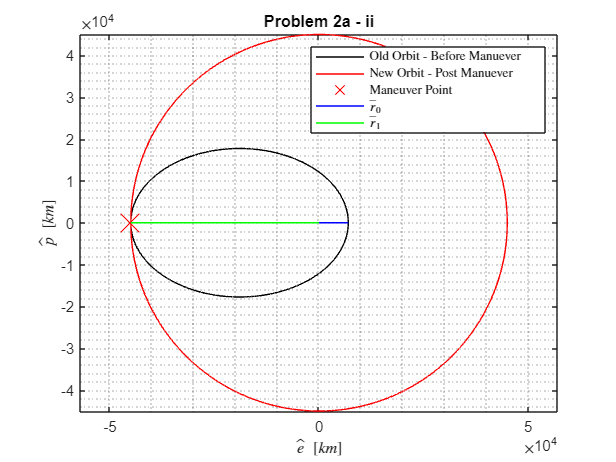

% True anomaly vector
ta_vec  = 0:.01:360;

% Semi-latus rectum of old orbit
p       = a*(1 - e^2);

% Initialize position vectors - in perifocal coordinates
r_P_old = zeros(2,length(ta_vec));
r_P_new = r_P_old;

for i = 1:length(ta_vec)

    % Calculate orbit radii
    r_old           = p/(1 + e*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R         = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                       sind(ta_vec(i)), cosd(ta_vec(i))];
    
    % Rotate vectors from orbit frame to perifocal frame
    r_P_old(:,i)    = P_DCM_R*[r_old;0];
    r_P_new(:,i)    = P_DCM_R*[ra;0];
end

figure
plot(r_P_old(1,:), r_P_old(2,:),'-k')
hold on
plot(r_P_new(1,:), r_P_new(2,:),'-r')
plot(-ra, 0,'rx','MarkerSize',18)
plot([0 rp],[0 0],'-b')
plot([-ra 0],[0 0],'-g')
grid minor
xlabel('$\hat{e} \  [km]$', 'Interpreter','latex')
ylabel('$\hat{p} \ [km]$', 'Interpreter','latex')
axis equal
title('Problem 2a - ii')
legend('Old Orbit - Before Manuever','New Orbit - Post Manuever','Maneuver Point',...
       '$\bar{r}_0$','$\bar{r}_1$','Interpreter','latex')